M = 45; As = 60; n=[0:1:M-1];
beta = 0.1102*(As-8.7)+0.3

beta = 5.9533

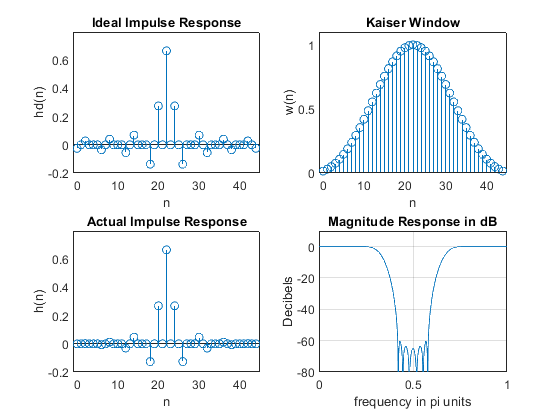

w_kai = (kaiser(M,beta))'; wc1 = pi/3; wc2 = 2*pi/3;
hd = ideal_lp(wc1,M) + ideal_lp(pi,M) - ideal_lp(wc2,M);
h = hd .* w_kai;
[db,mag,pha,grd,w] = freqz_m(h,[1]);
% Plots
figure;
subplot(2,2,1); stem(n,hd);
title('Ideal Impulse Response')
axis([-1 M -0.2 0.8]); xlabel('n'); ylabel('hd(n)')
subplot(2,2,2); stem(n,w_kai);title('Kaiser Window')
axis([-1 M 0 1.1]); xlabel('n'); ylabel('w(n)')
subplot(2,2,3); stem(n,h);title('Actual Impulse Response')
axis([-1 M -0.2 0.8]); xlabel('n'); ylabel('h(n)')
subplot(2,2,4);plot(w/pi,db); axis([0 1 -80 10]);
title('Magnitude Response in dB');grid;
xlabel('frequency in pi units'); ylabel('Decibels');

delta_w = 2*pi/1000;

clear
Rp = 1;
As = 60;
Fs = 1200; % Fs/2 = 600 is pi
% we need frequencies of pi/3 2pi/3
df = 20;
fcl = 200;
fcu = 400;
f = [fcl-df fcl+df fcu-df fcu+df];
a = [1 0 1];
d1 = (1-db2mag(-Rp))/(1+db2mag(-Rp))

d1 = 0.0575

d2 = db2mag(-As)*(1+d1)

d2 = 0.0011

d=[ d1 d2 d1];

[M, fo, ao, W]=firpmord(f,a,d,Fs);
M

M = 64

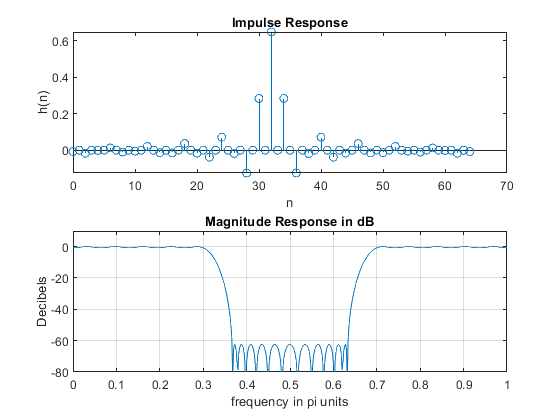

h = firpm(M,fo, ao, W);
n = 0:1:length(h)-1;
[db,mag,pha,grd,w] = freqz_m(h,[1]); 
delta_w = 2*pi/1000; 
% Plots
figure;
subplot(2,1,1); stem(n,h);title('Impulse Response') 
%axis([0 N -0.1 0.3]);
xlabel('n'); ylabel('h(n)') 
subplot(2,1,2);plot(w/pi,db);title('Magnitude Response in dB');
grid; 
axis([0 1 -80 10]); 
xlabel('frequency in pi units'); ylabel('Decibels') 

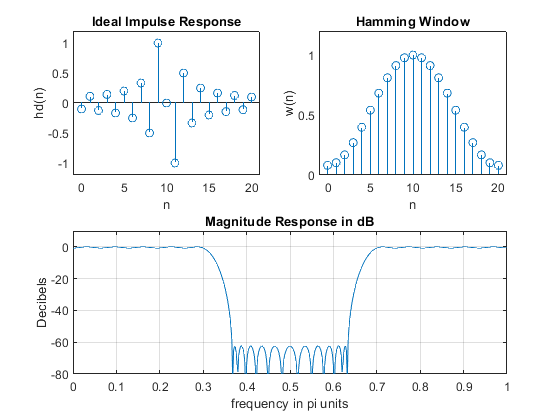

M = 21; alpha = (M-1)/2; n = 0:M-1; 
hd = (cos(pi*(n-alpha)))./(n-alpha); hd(alpha+1)=0; 
w_ham = (hamming(M))'; h = hd .* w_ham; [Hr,w,P,L] = Hr_Type3(h);
% plots 
subplot(2,2,1); stem(n,hd); title('Ideal Impulse Response') 
axis([-1 M -1.2 1.2]); xlabel('n'); ylabel('hd(n)') 
subplot(2,2,2); stem(n,w_ham);title('Hamming Window') 
axis([-1 M 0 1.2]); xlabel('n'); ylabel('w(n)') 

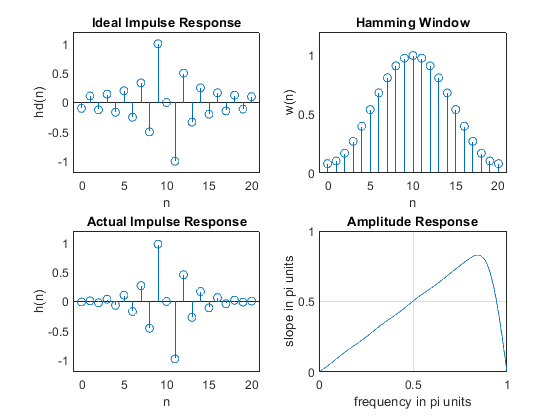

subplot(2,2,3); stem(n,h);title('Actual Impulse Response') 
axis([-1 M -1.2 1.2]); xlabel('n'); ylabel('h(n)') 
subplot(2,2,4);plot(w/pi,Hr/pi); title('Amplitude Response');grid; 
xlabel('frequency in pi units'); ylabel('slope in pi units'); axis([0 1 0 1]); 

clear;
Rp = 1;
% As = 60;
Fs = 1200; % Fs/2 = 600 is pi
% we need vector of amplitudes that is tied to the frequencies
% 
L = 50;
wcs = 0.01:1/L:0.99;
fcs = (0.01:1/L:0.99)*600;

for i =2:2:length(fcs)-2
a(i/2) = (wcs(i) + wcs(i+1))/2;
end
a = [0 a (1+wcs(L))/2];
a'

ans =          0
    0.0400
    0.0800
    0.1200
    0.1600
    0.2000
    0.2400
    0.2800
    0.3200
    0.3600


d = ones(1,length(a))*(1-db2mag(-Rp))/(1+db2mag(-Rp))

d =     0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575    0.0575


length(fcs)

ans = 50

length(a)

ans = 26

[M, fo, ao, W]=firpmord(fcs,a,d,Fs);
M

M = 100

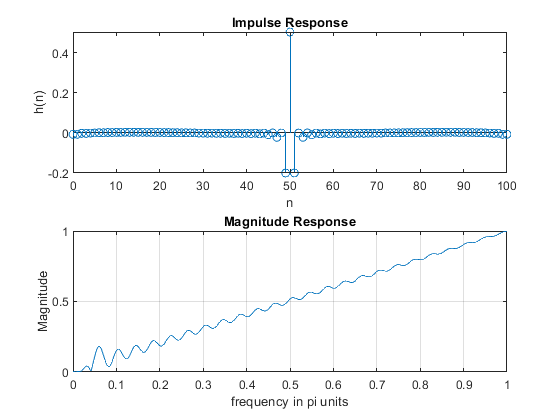

h = firpm(M,fo, ao, W);
n = 0:1:length(h)-1;
[db,mag,pha,grd,w] = freqz_m(h,[1]); 
delta_w = 2*pi/1000; 
% Plots
figure;
subplot(2,1,1); stem(n,h);title('Impulse Response') 
%axis([0 N -0.1 0.3]);
xlabel('n'); ylabel('h(n)') 
subplot(2,1,2);plot(w/pi,mag);title('Magnitude Response');
grid; 
xlabel('frequency in pi units'); ylabel('Magnitude');